### Global Variables

prec = 100;
digits(prec);

### Precision Tests

#### `Single-Mode and Onedimensional Function with x = 1.0`

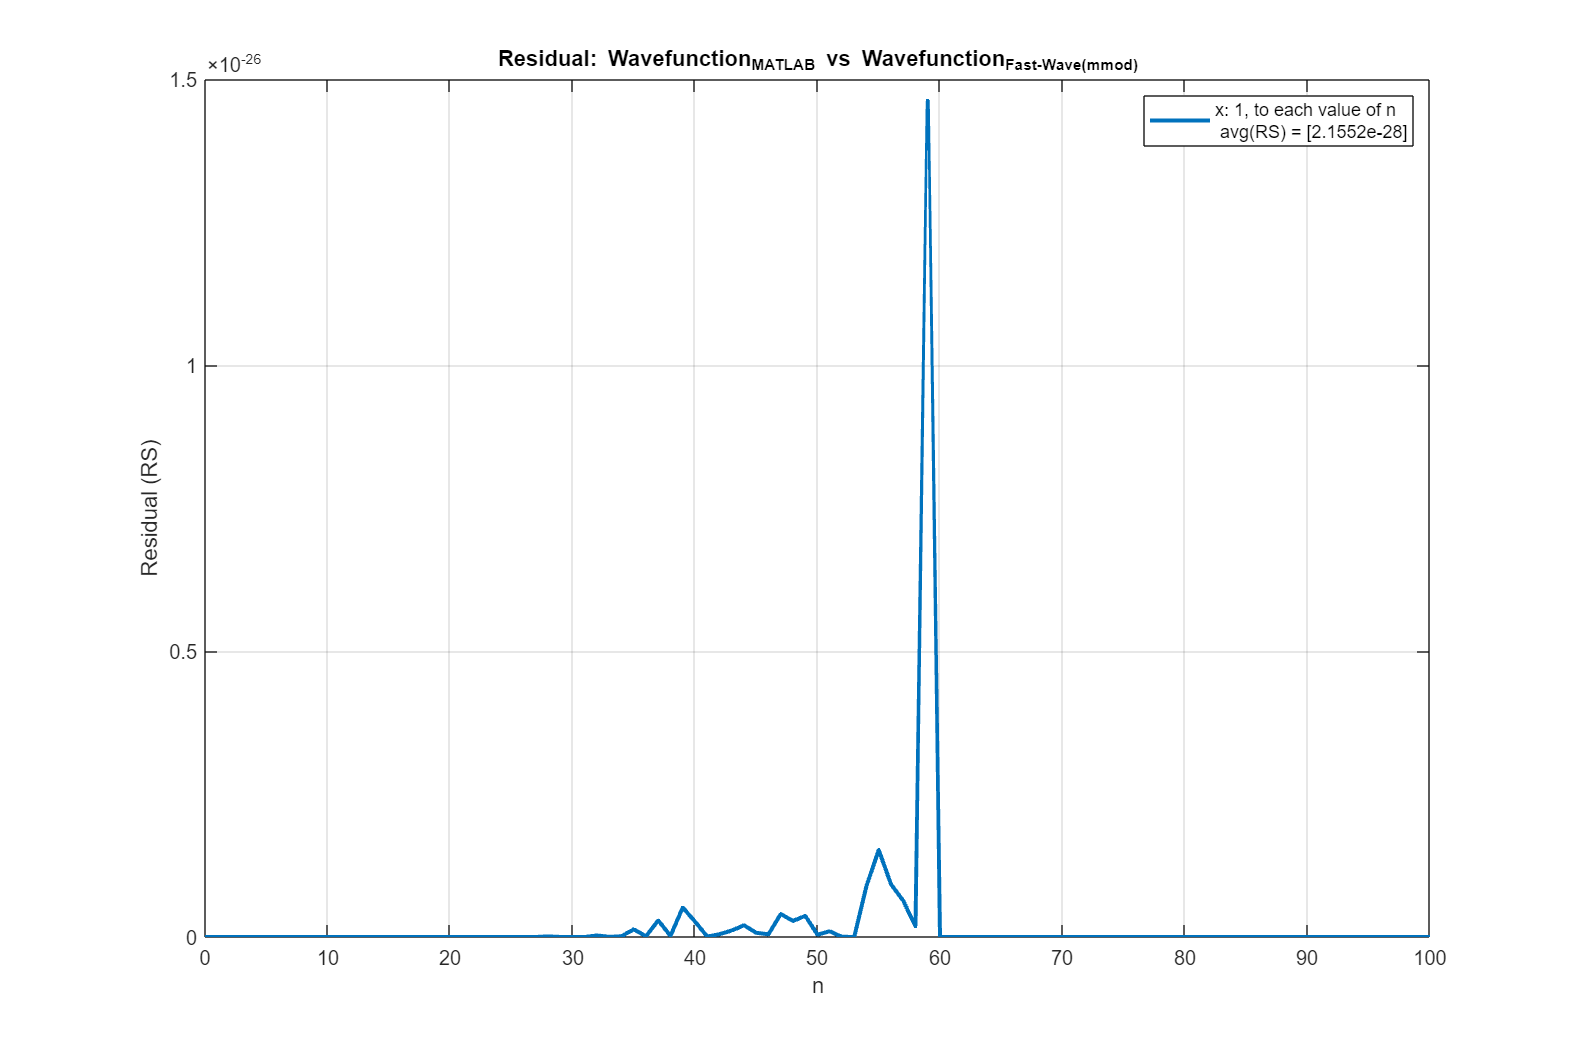

import py.fast_wave.wavefunction.wavefunction_smod

N_max = 100;
x = 1.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index, x, prec) - vpa(wavefunction_smod(uint64(index), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf('x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mmod)}');

#### `Single-Mode and Onedimensional Function with x = 50.0`

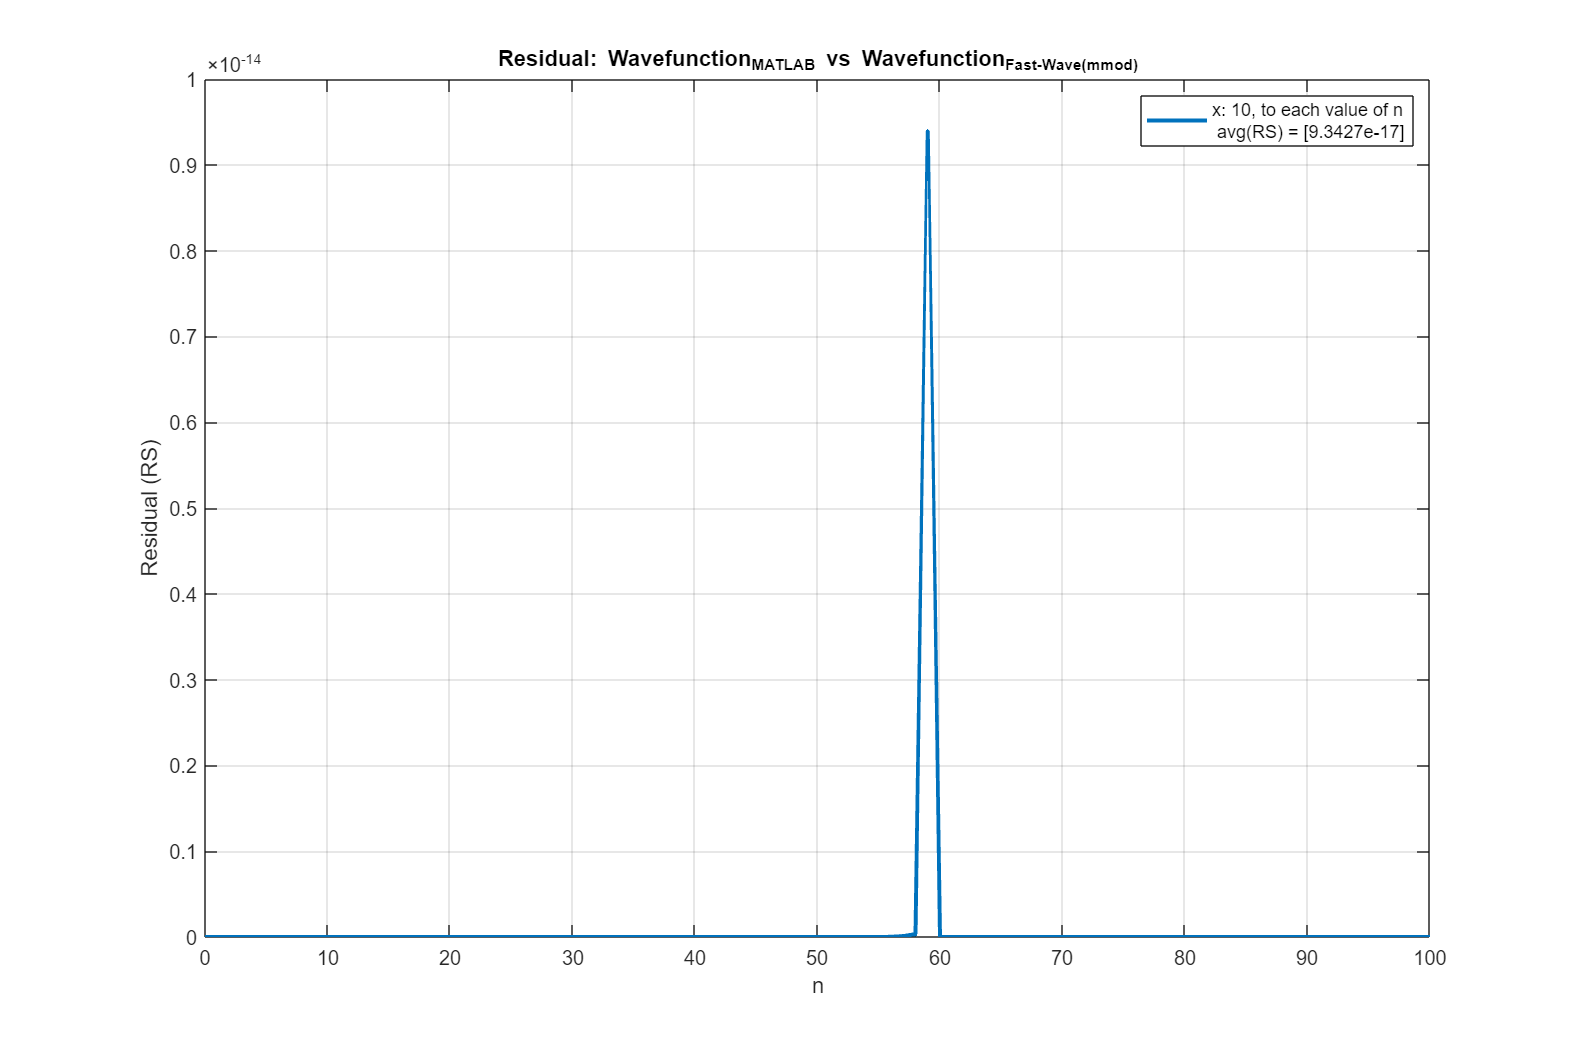

import py.fast_wave.wavefunction.wavefunction_smod

N_max = 100;
x = 10.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index, x, prec) - vpa(wavefunction_smod(uint64(index), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf('x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mmod)}');

#### `Single-Mode and Onedimensional Function with x = 20.0`

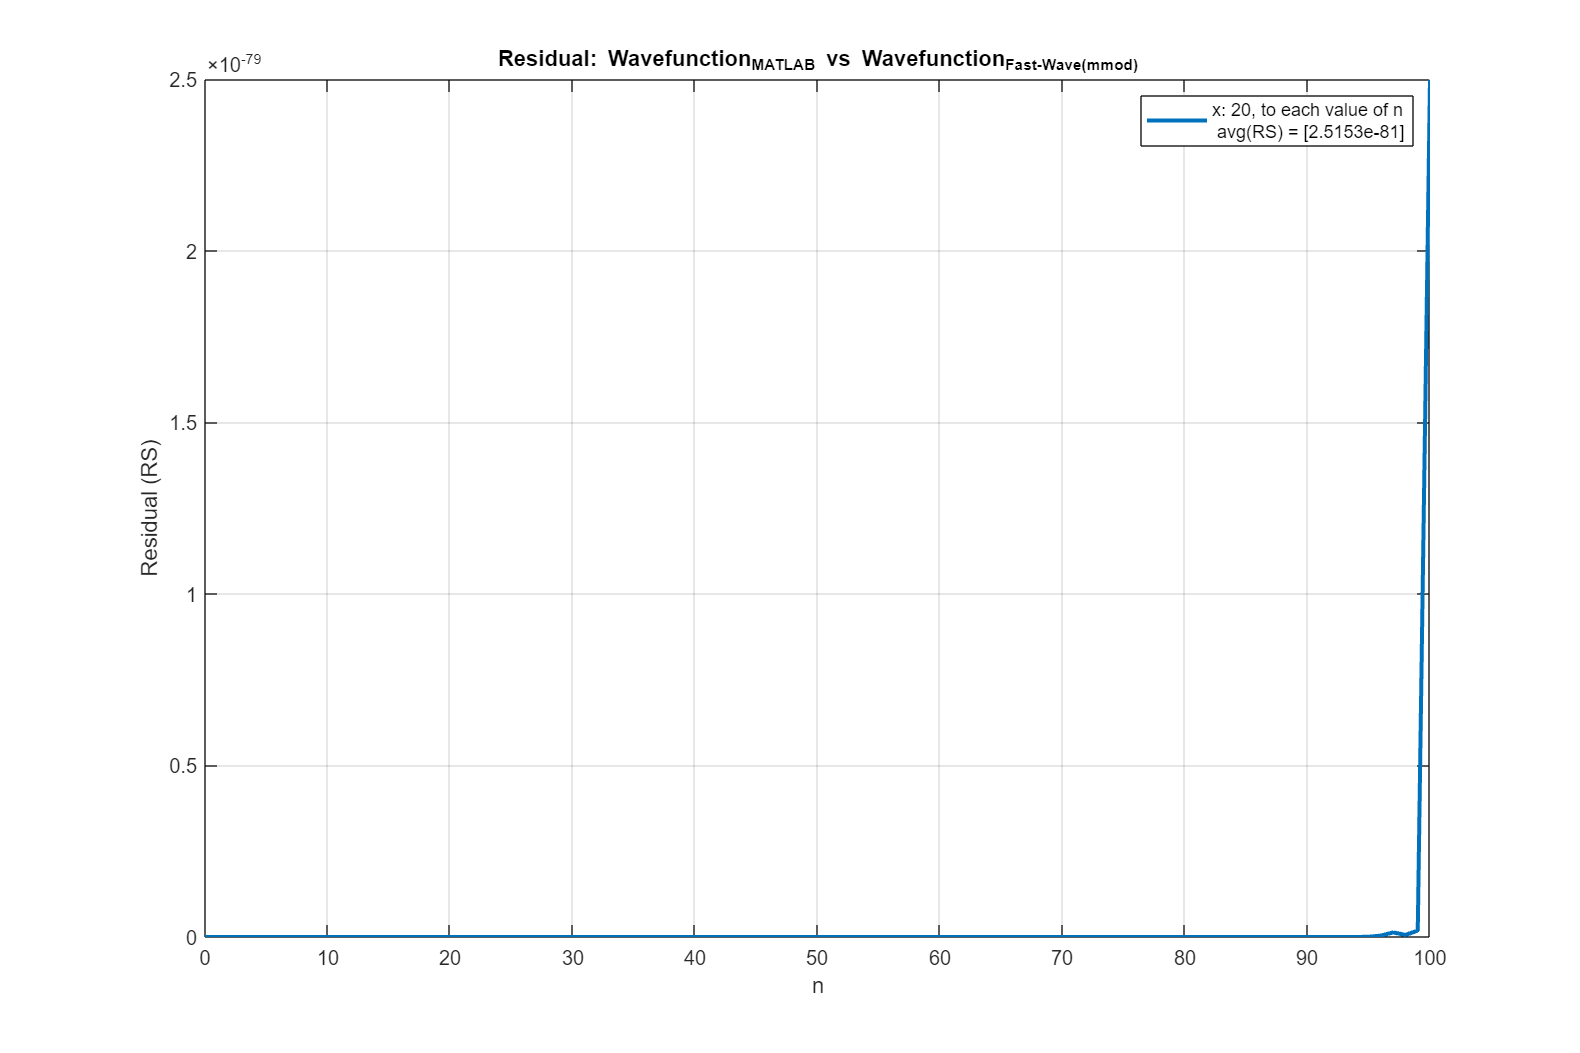

import py.fast_wave.wavefunction.wavefunction_smod

N_max = 100;
x = 20.0;

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = (wavefunction_MATLAB_1(index, x, prec) - vpa(wavefunction_smod(uint64(index), x)))^2;
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf('x: ' + string(x)+', to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mmod)}');

#### `Single-Mode and Multidimensional Function with x = 20.0`

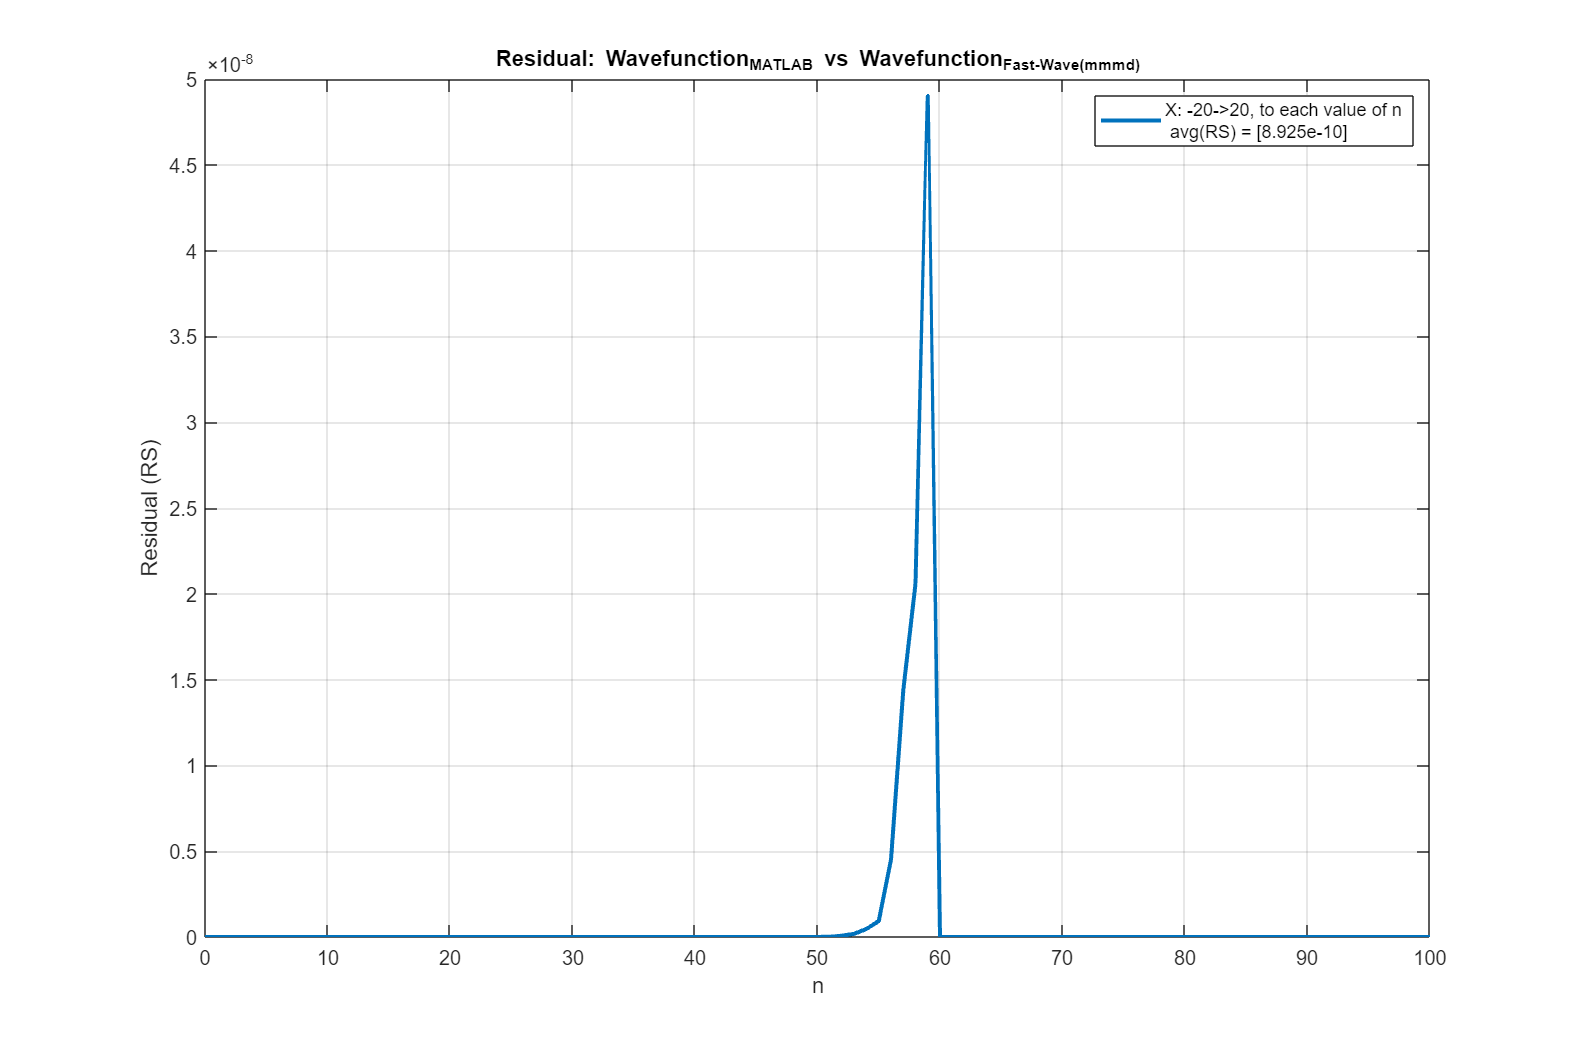

import py.fast_wave.wavefunction.wavefunction_smmd

N_max = 100;
x_max = 20.0;
x_min = -20.0;
x_size = 100;
X = linspace(x_max,x_min,x_size);

Residual = vpa(zeros(N_max+1, 1));
x_axi_plot = linspace(0,N_max,N_max+1);

for index = 1:N_max+1
    Residual(index,:) = mean((wavefunction_MATLAB_1(index, X, prec) - vpa(double(wavefunction_smmd(uint64(index), py.tuple(X))))).^2);
end

figure('Position', [100, 100, 1200, 800]);
plot(x_axi_plot, Residual, 'LineWidth', 2); 
grid on;

xlabel('n');
ylabel('Residual (RS)');
legend(sprintf('X: -20->20, to each value of n \n avg(RS) = ['+ string(double(mean(Residual)))+']'));
title('Residual: Wavefunction_{MATLAB} vs Wavefunction_{Fast-Wave(mmmd)}');